# Import data from text file

## Set up the Import Options and import the data

clearvars
filename = "TSLAstockData.csv"

filename = "TSLAstockData.csv"

opts = delimitedTextImportOptions("NumVariables", 7);

% Specify range and delimiter
opts.DataLines = [392, 781];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["DateTime", "Open", "Var3", "Var4", "Close", "Var6", "Var7"];
opts.SelectedVariableNames = ["DateTime", "Open", "Close"];
opts.VariableTypes = ["datetime", "double", "string", "string", "double", "string", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["Var3", "Var4", "Var6", "Var7"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Var3", "Var4", "Var6", "Var7"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "DateTime", "InputFormat", "dd/MM/yyyy HH:mm");

% Import the data
TSLA = readtable(filename, opts);

## Parameters for the Shallow Network

clear opts %Clear temporary variables
delete(gcp('nocreate'));
ratio = 0.86; % portion to split the data in training and testing
MaxEpochs = 600; % Max epoch for both net

## Gathering calibration data

% throw away the first 5 minutes of trading data
TSLA = TSLA(6:390,:);

% set period range
Period = size(TSLA,1);
Past = 5;Date = Past:Period+4;

% calculate stock price VP
SD = 11/15

SD = 0.7333

TSLA.VP = TSLA.Open*4/11 + SD*TSLA.Close

TSLA = 385×4 table
        DateTime         Open     Close       VP  
    ________________    ______    ______    ______

    03/05/2022 09:35    892.06       894    979.99
    03/05/2022 09:36       894     895.9    982.08
    03/05/2022 09:37    895.74    893.04    980.62
    03/05/2022 09:38    893.28    894.19    980.57
    03/05/2022 09:39    894.12    894.47    981.08
    03/05/2022 09:40    894.27    895.64    981.99
    03/05/2022 09:41       896    893.91    981.35
    03/05/2022 09:42    894.34    897.81    983.61
    03/05/2022 09:43    897.88    896.61    984.01
    03/05/2022 09:44    896.22    894.26    981.69
    03/05/2022 09:45     893.6    892.34    979.33
    03/05/2022 09:46    892.25    894.03    980.08
    03/05/2022 09:47    894.47    896.75    982.88
    03/05/2022 09:48    896.59    897.18    983.96
    03/05/2022 09:49    897.


data = transpose(TSLA.VP)

data = 	1.0e+03 *

    0.9800    0.9821    0.9806    0.9806    0.9811    0.9820    0.9813    0.9836    0.9840    0.9817    0.9793    0.9801    0.9829    0.9840    0.9863    0.9906    0.9986    0.9984    0.9968    0.9988    0.9989    1.0025    1.0057    1.0062    1.0093    1.0117    1.0119    1.0109    1.0097    1.0089    1.0080    1.0071    1.0051    1.0031    1.0021    1.0014    1.0011    0.9993    0.9996    1.0033    1.0014    0.9981    0.9972    0.9963    0.9979    0.9982    0.9954    0.9942    0.9927    0.9926


## Visualize the data

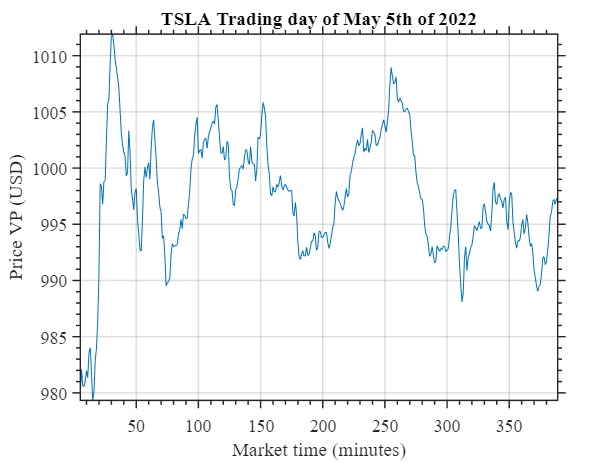

figure
plot(Date,TSLA.VP)
xlabel("Market time (minutes)")
ylabel("Price VP (USD)")
title("TSLA Trading day of May 5th of 2022")
set(gca,'FontSize',12,'FontName','Adobe Kaiti Std R','FontWeight','bold');
set(gca, 'Box', 'on', 'LineWidth', 1, 'Layer', 'top',...
    'XMinorTick', 'on', 'YMinorTick', 'on', 'XGrid', 'on', 'YGrid', 'on', ...
    'TickDir', 'out', 'TickLength', [.015 .015],...
    'FontName', 'avantgarde', 'FontSize', 12, 'FontWeight', 'normal');axis tight

## Split the data to training and testing sets

numStepsTraining = round(ratio*numel(data));
indexTrain = 1:numStepsTraining;
dataTrain = data(indexTrain );
dateTrain = Date(indexTrain);

indexTest = numStepsTraining+1:size(data,2);
dataTest = data(indexTest);
dateTest = Date(indexTest);

% Prepare the data
XTrain = tonndata(dataTrain',false,false);
XTest = tonndata(dataTest',false,false);

## Optimize hyperparameters

% let see how many cores we have....
info = feature('numcores');
parpool('local',info(1));

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


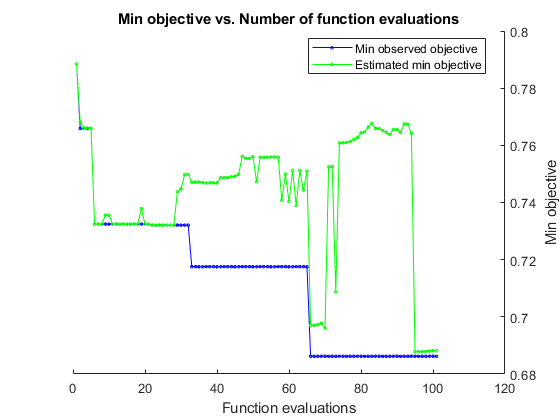

    % Shallow Network Optimization
    optimVars = [
        optimizableVariable('learningrate',[1e-5 1e-2],'Type','real','Transform',"log")
        optimizableVariable('performFcn',{'mse' 'mae' 'sse' 'msesparse'},'Type','categorical')
        optimizableVariable('mc',[5e-1 0.99],'Type','real',"Transform","log")
        optimizableVariable('processFcns',{'mapminmax' 'mapstd'},'Type','categorical')
        optimizableVariable('Lag',[5 20],'Type','integer')
        optimizableVariable('hiddenLayerSize1',[7 25],'Type','integer')
        optimizableVariable('hiddenLayerSize2',[7 25],'Type','integer')];

    % Objective function
    ObjFcnSN = makeObjFcnSN(XTrain,XTest,MaxEpochs);

    % repeat the result....well trying to
    rng(0);
    % call optimizer
    BayesObject = bayesopt(ObjFcnSN,optimVars, ...
        'MaxTime',10*60*60, ...
        'Verbose',0,...
        'NumSeedPoints',info(1),...
        "UseParallel",true,...
        'ParallelMethod',"model-prediction",...
        'IsObjectiveDeterministic',false, ...
        'MaxObjectiveEvaluations',100,...
        'ExplorationRatio',0.7,...
        'AcquisitionFunctionName', 'expected-improvement-per-second-plus');


    % get the best point of the Bayesian Optimizaion
    optVars = bestPoint(BayesObject),

optVars = 1×7 table
    learningrate    performFcn      mc       processFcns    Lag    hiddenLayerSize1    hiddenLayerSize2
    ____________    __________    _______    ___________    ___    ________________    ________________

     0.00050617        sse        0.96737      mapstd       20            23                  7        


    % Evaluate and train the network with the optimal parameters
    [err,~,net,Xsf,Asf, xtest, YTest] = BayesObject.ObjectiveFcn(optVars,true);

    % Test the network
    [YPred,Xf,Af]  = net(xtest, Xsf, Asf);

    % net Performance respect to the Testing sequence
    sMAPErr = sMAPE(YTest,YPred);
    YPred = cell2mat(YPred);YTest = cell2mat(YTest);
delete(gcp('nocreate'));

## Visualizing testing and predicted data in scale of full dataset

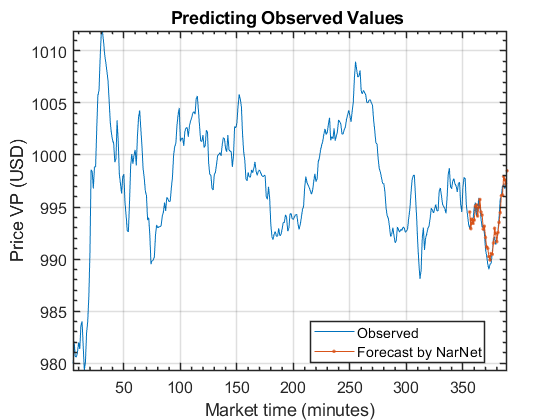

figure
plot(Date,data);
hold on
idx = size(YPred,2);
plot(Date(end)-idx+1:Date(end), YPred,'.-');
xlabel("Market time (minutes)")
ylabel("Price VP (USD)")
title("Forecast")
legend(["Observed" "Forecast by NarNet"],'Location',"best")
title('Predicting Observed Values ')
set(gca,'FontSize',12,'FontName','Adobe Kaiti Std R','FontWeight','bold');
set(gca, 'Box', 'on', 'LineWidth', 1.1, 'Layer', 'top',...
    'XMinorTick', 'on', 'YMinorTick', 'on', 'XGrid', 'on', 'YGrid', 'on', ...
    'TickDir', 'in', 'TickLength', [.015 .015],...
    'FontName', 'avantgarde', 'FontSize', 12, 'FontWeight', 'normal');axis tight

## Visualize isolated predicted data in respect to test data

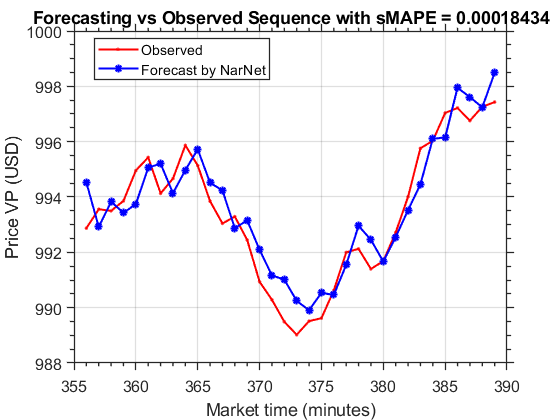

figure
plot(Date(end)-idx+1:Date(end),YTest,'r.-','LineWidth',1.5)
hold on
plot(Date(end)-idx+1:Date(end),YPred,'b*-','LineWidth',1.5);
legend(["Observed" "Forecast by NarNet"],"Location","best")
xlabel("Market time (minutes)")
ylabel("Price VP (USD)")

title("Forecasting vs Observed Sequence with sMAPE = " + sMAPErr)
set(gca,'FontSize',12,'FontName','Adobe Kaiti Std R','FontWeight','bold');
set(gca, 'Box', 'on', 'LineWidth', 1, 'Layer', 'top',...
    'XMinorTick', 'on', 'YMinorTick', 'on', 'XGrid', 'on', 'YGrid', 'on', ...
    'TickDir', 'out', 'TickLength', [.015 .015],...
    'FontName', 'avantgarde', 'FontSize', 12, 'FontWeight', 'normal');

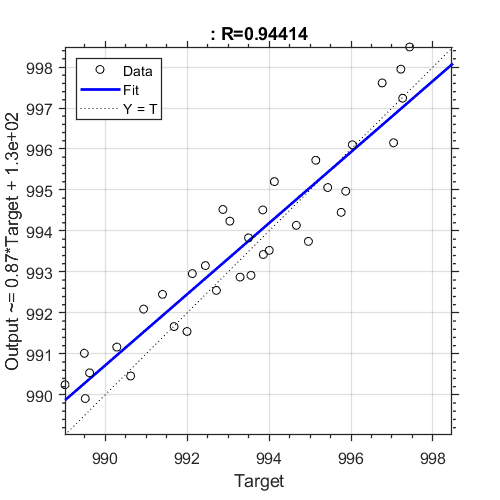

plotregression(con2seq(YTest),con2seq(YPred));
set(gca,'FontSize',12,'FontName','Adobe Kaiti Std R','FontWeight','bold');
set(gca, 'Box', 'on', 'LineWidth', 1, 'Layer', 'top',...
    'XMinorTick', 'on', 'YMinorTick', 'on', 'XGrid', 'on', 'YGrid', 'on', ...
    'TickDir', 'out', 'TickLength', [.015 .015],...
    'FontName', 'avantgarde', 'FontSize', 12, 'FontWeight', 'normal');

## Forecast unobserved values

    numTimeStepsTest = size(YTest,2);
    [x1,xio,aio,t] = preparets(net,{},{},XTrain);
    [y1,xfo,afo] = net(x1,xio,aio);
    [netc,xic,aic] = closeloop(net,xfo,afo);
    X2 = num2cell(rand(1,numTimeStepsTest));
    [YPredStep,xfc,afc] = netc(X2,xic,aic);
    YPredStep = cell2mat(YPredStep);

## visualize the performance

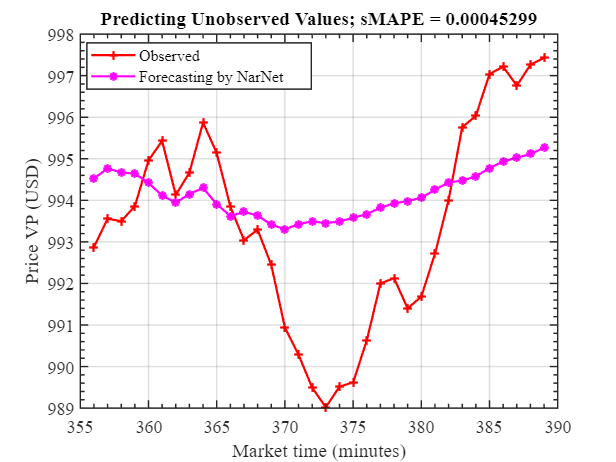

% evaluate the net performance
sMAPErr = sMAPE(con2seq(YTest) ,con2seq(YPredStep));
figure
plot(Date(end)-idx+1:Date(end),YTest,'r+-','LineWidth',1.5)
hold on
plot(Date(end)-idx+1:Date(end),YPredStep,'m*-','LineWidth',1.5);
legend({"Observed","Forecasting by NarNet"},"Location","best")
xlabel("Market time (minutes)")
ylabel("Price VP (USD)")
title("Predicting Unobserved Values; sMAPE = " + sMAPErr)
set(gca,'FontSize',12,'FontName','Adobe Kaiti Std R','FontWeight','bold');
set(gca, 'Box', 'on', 'LineWidth', 1, 'Layer', 'top',...
    'XMinorTick', 'on', 'YMinorTick', 'on', 'XGrid', 'on', 'YGrid', 'on', ...
    'TickDir', 'in', 'TickLength', [.015 .015],...
    'FontName', 'avantgarde', 'FontSize', 12, 'FontWeight', 'normal');

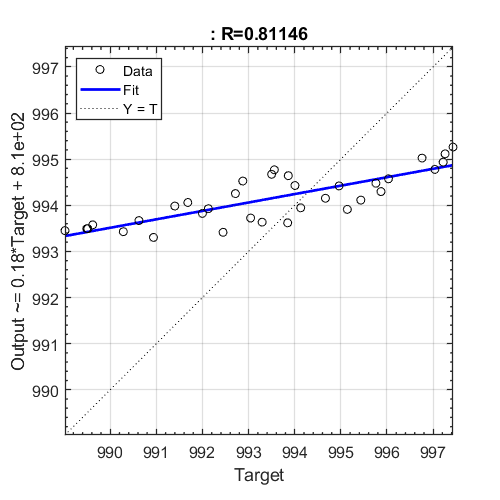

plotregression(con2seq(YTest),con2seq(YPredStep));
set(gca,'FontSize',12,'FontName','Adobe Kaiti Std R','FontWeight','bold');
set(gca, 'Box', 'on', 'LineWidth', 1, 'Layer', 'top',...
    'XMinorTick', 'on', 'YMinorTick', 'on', 'XGrid', 'on', 'YGrid', 'on', ...
    'TickDir', 'in', 'TickLength', [.015 .015],...
    'FontName', 'avantgarde', 'FontSize', 12, 'FontWeight', 'normal');

### Local Functions

function ObjFcn = makeObjFcnSN(XTrain,XTest,MaxEpochs)
ObjFcn = @valErrorFun;
    function [valError,emp,net,Xsf, Asf, xtest, YTest] = valErrorFun(optVars,mviz)
        emp = [];
        % Create a Nonlinear Autoregressive Network
        net = narnet(1:optVars.Lag,[optVars.hiddenLayerSize1 optVars.hiddenLayerSize2 ],...
            'open','trainbr');
        [xtest,xits,aits,YTest] = preparets(net,{},{},XTest);
        [xtrain,xitr,aitr,YTrain] = preparets(net,{},{},XTrain);

        % training parameters
        net.trainParam.epochs = MaxEpochs ; % Maximum number of epochs to train
        net.trainParam.goal = 1e-6;   % Performance goal
        net.trainParam.lr = optVars.learningrate;     % Learning rate
        net.trainParam.max_fail = 30; % Maximum validation failures
        net.trainParam.mc = optVars.mc;     % Momentum constant
        if ~exist('mviz')
            net.trainParam.showWindow = false;%Show training GUI
        else
            net.trainParam.showWindow = true;%Show training GUI
        end
        % Set up Division of Data for Training, Validation, Testing
        net.divideFcn = 'dividerand';  % Divide data randomly help nndivision
        net.divideMode = 'time';  % Divide up every sample
        net.divideParam.trainRatio = 0.7;
        net.divideParam.valRatio = 0.15;
        net.divideParam.testRatio = 0.15;
        % help nnperformance
        net.performFcn = string(optVars.performFcn);  % Mean Squared Error
        %help nnplot
        net.plotFcns = {'plotperform','plottrainstate', 'ploterrhist', ...
            'plotregression', 'plotresponse', 'ploterrcorr', 'plotinerrcorr'};
        % help nnprocess
        net.input.processFcns = {'removeconstantrows',char(optVars.processFcns)};

        % weigth bias  initialization to zero
        net = setwb(net,zeros(net.numWeightElements,1));
        rng(0);
        % Train the Network
        [net,tr,Ys, Es, Xsf, Asf] = train(net,xtrain,YTrain,xitr,aitr);

        valError = mae(cell2mat(YTrain)-cell2mat(Ys)) ;

    end
end

Metric Calculation

function E = sMAPE(YTest,YPred)
YPred = cell2mat(YPred);YTest = cell2mat(YTest);
E = 0.5*mean(abs(YPred(:)-YTest(:))./(abs(YPred(:))+abs(YTest(:))));
end